## Лаба 4. Точностные свойства системы, астатизмы и регуляторы

## Задание 1. Стабилизация с идеальным дифференцирующим звеном

simTimeStart = 0;
simTimeEnd = 5;
step = 0.02;
data.time=(simTimeStart:0.02:simTimeEnd)';
modelName = 'task1'; 

### Моделирование свободного движения - разомкнутая система

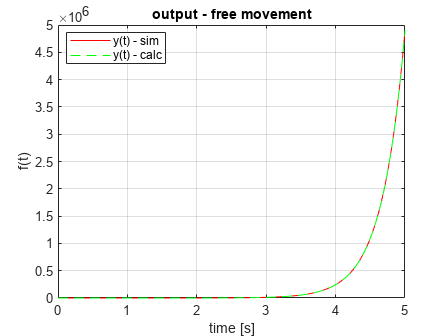

a0 = -3 ; a1 = -2 ; a2 =1; % coeff of the system
y0 = 3; y1 = 3; % initial state

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
y_analytical = 1.5 * ( exp(-1*time) + exp(3*time) ); 

figure;
plot(time, y_out, 'r');
hold on;
plot(time, y_analytical, 'g--');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'y(t) - calc', 'Location', 'Best');
save_file('output_task1_exp1')

simTimeStart = 0;
simTimeEnd = 10;
step = 0.02;
data.time=(simTimeStart:step:simTimeEnd)';
modelName = 'task12'; 

lambda1 = 3; lambda2 = -1;
k0 = -6; k1 = -4;

### Моделирование - замкнутая система

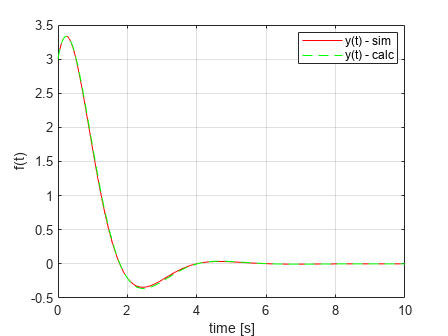

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
y_analytical = exp(-time).*( 3.*cos(sqrt(2).*time) + (6/sqrt(2)) .*sin(sqrt(2).*time) ); 

figure;
plot(time, y_out, 'r');
hold on;
plot(time, y_analytical, 'g--');
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'y(t) - calc', 'Location', 'Best');
save_file('output_task1_exp2')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab4\latex4\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end